close all
clear all
clc
s = tf('s');
% This file aims to translate the different plant requirements into wp and wt, such that
% robust contorl theory can be applied

## Example 1: Steady state error requirement

Plant with 50% ss err:

L = 10/(s+10);
T = L/(1+L);
S = 1/(1+L)

S =
 
  s + 10
  ------
  s + 20
 
Continuous-time transfer function.
Model Properties


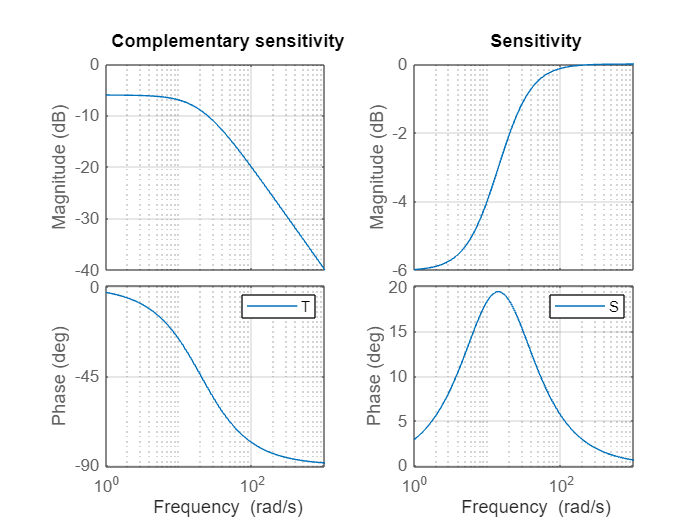


subplot(1,2,1);
bode(T);
title("Complementary sensitivity");
legend("T");
grid on
subplot(1,2,2);
bode(S);
title("Sensitivity");
legend("S");
grid on
hold off

Steady state error shaping:

w_p(0) = 1/err

proof:

 err = 1- lim s->0 T(s), T(s) = 1- S(s)

Example:

If, now, a err <= 25% requirement is set with wp:

figure
w_p = 1/(0.25*(0.5*s+1)/(0.1*s+1))

w_p =
 
    0.1 s + 1
  --------------
  0.125 s + 0.25
 
Continuous-time transfer function.
Model Properties


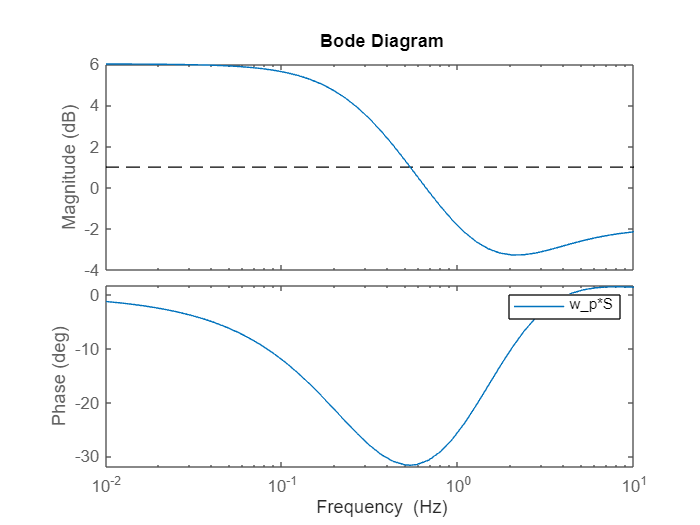

plot(opts.XLim{1}/10,[1,1],'--k');
hold on
h = bodeplot(S*w_p);
opts = getoptions(h);
opts.FreqUnits = 'Hz';
setoptions(h,opts)
legend("w_p*S");

It can be seen that S(0)*w_p(0) = 6 dB. That means S is missing a factor of 2 to ensure the 25% error, as currently the error is 50%.

For ensuring the steady state error of higher order use:

w_p = 1/(s^(order)*err)

So, for a 5% 1st order error (for a line, input of 1/s), w_p = 1/(0.05*s) = 20/s

L_10 = 10/s % 10% error

L_10 =
 
  10
  --
  s
 
Continuous-time transfer function.
Model Properties


S_10 = 1/(1+L_10);
L_5 = 20/s % 5% error

L_5 =
 
  20
  --
  s
 
Continuous-time transfer function.
Model Properties


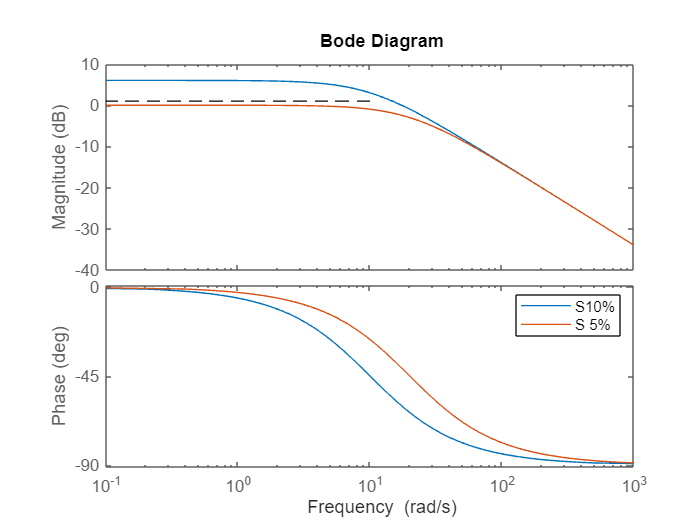

S_5 = 1/(1+L_5);
w_p = 20/s;
figure
plot(opts.XLim{1}/10,[1,1],'--k');
hold on
h = bodeplot(S_10*w_p,S_5*w_p);
legend("S10%","S 5%");

The plant with 10% error does not satisfy the requirement, but the one with 5% does.

## Settling time requirement